# **IO292 - Digital Loopback**

This example shows you how to perform a loopback test with the IO292 I/O module to verify the functionality of some of the channels.

The IO292 I/O module provides a total of 24 digital TTL lines and supports a 24 mA source/sink current. The channels are organized into three banks (A, B and C) and can be configured as inputs or outputs in groups of eight, with the exception of bank C (I/O channels 17-24) which can be split into two groups of four I/O lines.

Channels are activated and configured in the [IO292 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io292_setup) block. The [Digital Input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io292_digital_input) and [Digital Output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io292_digital_output) blocks always act on all the active channels (input or output).

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO292 I/O module installed

- 2x connector cable from the I/O module to the terminal board

- 1 x 2-way 17-pin M12 terminal board with jumper wires

### Test Setup

In this example, channels 1-4 are configured as outputs, and channels 9-12 are configured as inputs.

Connect the outputs to the inputs according to the following table.

The complete pin mapping of the IO292 can be found in the documentation: [IO292 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io292_pin_mapping) 

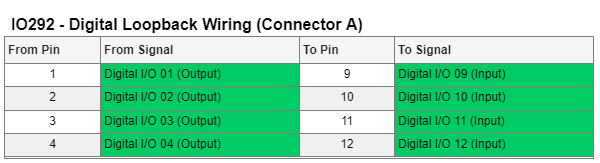

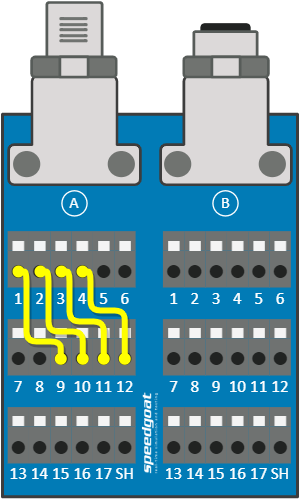

## Open the Simulink model

 
% Open Simulink Model
modelName = 'sgMdl_IO292_DigitalLoopback';
open_system(modelName);

### Model Description

The Simulink model features the [IO292 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io292_setup), [IO292 Digital Output](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io292_digital_output) and [IO292 Digital Input](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io292_digital_input) blocks.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

By clicking on the scope after the model run has terminated, you can inspect the signals. You should see 4 square waves, like in the image below:

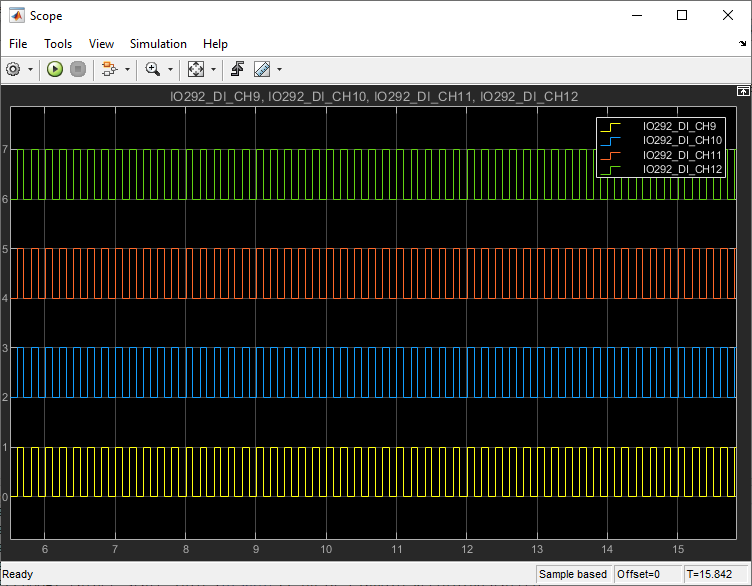

The model runs at a 1 kHz sample rate. The looped-back signal consists of a square wave with amplitude 1, a period of 200 samples and pulse width of 100 samples. The signals of the individual input channels are shifted to make them easily visible on the scope.

## Additional References

- [IO292 examples and documentation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io292)